CP = py.importlib.import_module('CoolProp.CoolProp');

# Exergy analysis - Single Pipeline

## Storage exergy

% Single pipeline
d = 0.9; % Diameter
L = 100000; % Length
% d = 30*0.00.254; % Total gas transmission network
% L = 7600000;
vol = (pi*d^2/4)*L

vol = 6.3617e+04

P_amb = 101325;
T_amb = 278;

P_pipe = 7e6;
P_pipe_max = P_pipe; % 70 bar
P_pipe_min = 2e6;

Assuming ideal gas, that the kinetic and potential exergies are neglectible and $T=T_o$


$$\begin{array}{l}
\phi \;=P_O \left(v-v_0 \right)-T_o \left(s-s_o \right)={\textrm{RT}}_o \left(\frac{P_o }{P}-1+\ln \;\frac{P}{P_o }\right)\\
\chi =m\;\phi =P\;\;\textrm{Vol}\;\left(\frac{P_o }{P}-1+\ln \;\frac{P}{P_o }\right)
\end{array}$$


X = P_pipe*vol*(P_amb/P_pipe - 1 + log(P_pipe/P_amb)) % Exergy in Joule

X = 1.4472e+12

X_MWh = X/(3600*1e6) % Total exergy [MWh]

X_MWh = 402.0018

X_max = P_pipe_max*vol*(P_amb/P_pipe_max - 1 + log(P_pipe_max/P_amb)) % Exergy when charged[J]

X_max = 1.4472e+12

X_min = P_pipe_min*vol*(P_amb/P_pipe_min - 1 + log(P_pipe_min/P_amb)) % Exergy when discharged[J]

X_min = 2.5870e+11

X_op = X_max - X_min; 

X_max_MWh = X_max./(3600*1e6)

X_max_MWh = 402.0018

X_min_MWh = X_min./(3600*1e6)

X_min_MWh = 71.8603


X_op_MWh = X_op/(3600*1e6) % Difference in exergy between charged and discharged states 

X_op_MWh = 330.1415

# Exergy Graph

d = 0.9; % 0.25:0.05:1.50; % Diameter
L = 100e3; %[10:10:200].*1e3; % Length [m]

vol = (pi*d^2/4)*L

vol = 6.3617e+04

P_amb = 101325;
T_amb = 278;

P_pipe = 7e6;
P_pipe_max = [6e6:0.5e6:10e6];
P_pipe_min = [1e5:0.5e6:6e6];


Assuming ideal gas, that the kinetic and potential exergies are neglectible and $T=T_o$


$$\begin{array}{l}
\phi \;=P_O \left(v-v_0 \right)-T_o \left(s-s_o \right)={\mathrm{RT}}_o \left(\frac{P_o }{P}-1+\ln \;\frac{P}{P_o }\right)\\
\chi =m\;\phi =P\;\;\mathrm{Vol}\;\left(\frac{P_o }{P}-1+\ln \;\frac{P}{P_o }\right)
\end{array}$$


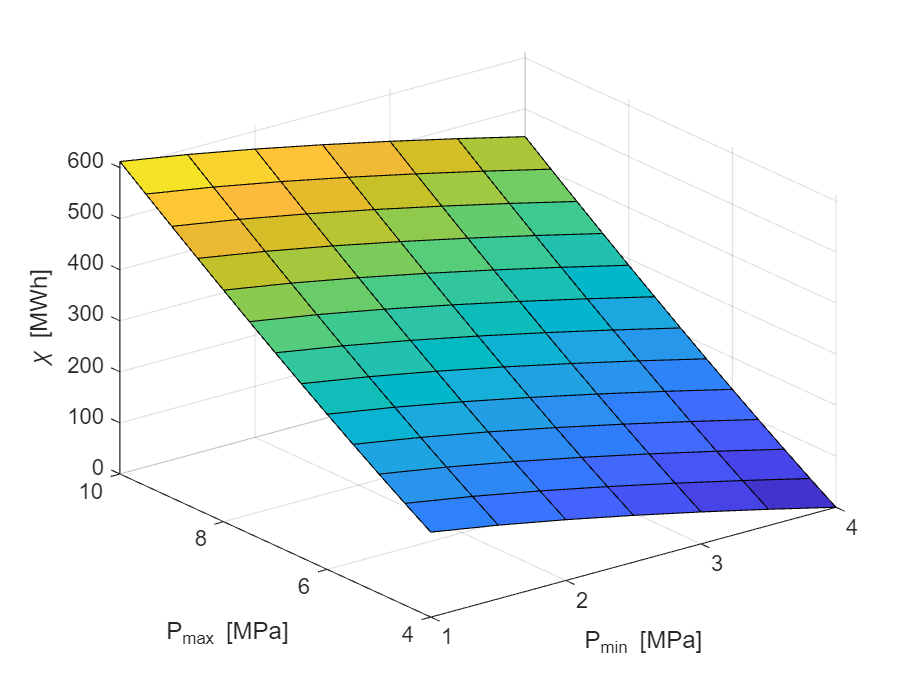

for i=1:length(P_pipe_max)
    X_max(i) = P_pipe_max(i)*vol*(P_amb/P_pipe_max(i) - 1 + log(P_pipe_max(i)/P_amb)); % Exergy when charged[J]
    X_max_MWh(i) = X_max(i)./(3600*1e6);
    for j = 1:length(P_pipe_min)        
        X_min(j) = P_pipe_min(j)*vol*(P_amb/P_pipe_min(j) - 1 + log(P_pipe_min(j)/P_amb)); % Exergy when discharged[J]
        X_min_MWh(j) = X_min(j)./(3600*1e6);
        X_op(i,j) = X_max_MWh(i) - X_min_MWh(j);
    end
end

% figure('Color',[1 1 1])
surf(P_pipe_min./1e6,P_pipe_max./1e6,X_op)
xlabel('P_{min} [MPa]')
ylabel('P_{max} [MPa]')
zlabel('\chi [MWh]')

## Flow exergy

m_dot = 198.6; % [kg/s] - Value proportional to the area based on total mass flow rate into St. Fergus
P = 7e6; % 7 MPa
T = 298;

D = 0.900;

P_o = P_amb;
T_o = T_amb;
h_o = CP.PropsSI('H','P',P_o,'T',T_o,'air');
s_o = CP.PropsSI('S','P',P_o,'T',T_o,'air');

h = CP.PropsSI('H','P',P,'T',T,'air');
s = CP.PropsSI('S','P',P,'T',T,'air');
rho = CP.PropsSI('D','P',P,'T',T,'air');

A_h = pi*D^2/4;
V = m_dot/(rho*A_h);
psi =  (h - h_o) - T_o*(s - s_o)+V^2/2; % + g*z ;
Psi = m_dot*psi % [W]

Psi = 6.6805e+07

Psi_MW = Psi/(1e6) % [MW]

Psi_MW = 66.8051

# Exergy analysis - Gas Transmission Network

## Storage exergy

% load('Pipe_data.mat')
% d = D_UK./1e3; % [mm] converted to [m]
% L = L_UK.*1e3; % [km] converted to [m]

load('pipelines_USA.mat')
% d = D_USA./1e3; % [mm] converted to [m]
d = 850/1e3; % weighted average diameter based on UK and EU [mm]
L = L_USA.*1e3; % [km] converted to [m]

% load('pipelines_Germany.mat')
% d = D_DE./1e3; % [mm] converted to [m]
% L = L_DE.*1e3; % [km] converted to [m]

% d = 0.9; % Diameter
% L = 70000; % Length
% d = 30*0.00.254; % Total gas transmission network
% L = 7600000;
vol = (pi.*d.^2/4).*L;
P_amb = 101325;
T_amb = 278;

P_pipe = 7e6;
P_pipe_max = P_pipe; % 70 bar
P_pipe_min = 2e6;

Assuming ideal gas, that the kinetic and potential exergies are neglectible and $T=T_o$


$$\begin{array}{l}
\phi \;=P_O \left(v-v_0 \right)-T_o \left(s-s_o \right)={\textrm{RT}}_o \left(\frac{P_o }{P}-1+\ln \;\frac{P}{P_o }\right)\\
\chi =m\;\phi =P\;\;\textrm{Vol}\;\left(\frac{P_o }{P}-1+\ln \;\frac{P}{P_o }\right)
\end{array}$$


X = P_pipe*vol*(P_amb/P_pipe - 1 + log(P_pipe/P_amb)); % Exergy in Joule
X_MWh = X/(3600*1e6); % Total exergy [MWh]
X_max = P_pipe_max*vol.*(P_amb/P_pipe_max - 1 + log(P_pipe_max/P_amb)); % Exergy when charged[J]
X_min = P_pipe_min*vol.*(P_amb/P_pipe_min - 1 + log(P_pipe_min/P_amb)); % Exergy when discharged[J]
X_op = X_max - X_min; 
X_op_MWh = X_op./(3600*1e6); % Difference in exergy between charged and discharged states
X_max_Tot = sum(X_max./(3600*1e9)) % [J converted to MWh converted to GWh]

X_max_Tot = 1.7363e+03

X_op_Tot = sum(X_op_MWh)/1e3 % [MWh converted to GWh]

X_op_Tot = 1.4259e+03

150*pi*20^2

ans = 1.8850e+05